# Intro

## Creazione di vettori e operazioni elemento per elemento tra vettori ("elementwise")

% In questo "quesito" si chiede di fare le operazioni forse più
% frequenti, tra vettori e matrici dello stesso ordine, cioè quelle
% "elemento per elemento"

% Dati
% Nessuno

% Domande
% a = vettore colonna con elementi 1, -3, 5, -6
% b = vettore colonna con elementi doppi di a
% c1 = vettore somma a + b, elemento per elemento
% c2 = vettore differenza a - b, elemento per elemento 
% c3 = vettore prodotto a*b, elemento per elemento 
% c4 = vettore rapporto a/b, elemento per elemento 
% c5 = vettore reciproco 1/a, elemento per elemento
% c6 = vettore elevamento al quadrato a^2, elemento per elemento

% Codice iniziale
clear

### Soluzione

a = [1; -3; 5;-6]

a =      1
    -3
     5
    -6


b = 2*a

b =      2
    -6
    10
   -12


b = 2.*a
c1 = a+b

c1 =      3
    -9
    15
   -18


c2 = a-b

c2 =     -1
     3
    -5
     6


c3 = a.*b

c3 =      2
    18
    50
    72


c4 = a./b

c4 =     0.5000
    0.5000
    0.5000
    0.5000


c5 = 1./a

c5 =     1.0000
   -0.3333
    0.2000
   -0.1667


c6 = a.^2

c6 =      1
     9
    25
    36


## Altre operazioni elemento per elemento

% Questo "quesito" è un proseguimento del precedente

% Dati
% Vettori a, b del quesito precedente

% Domande
% c1 = vettore valore assoluto di a
% c2 = vettore radice quadrata di a, usando sqrt
% c3 = vettore radice quadrata di a, usando ^
% c4 = vettore radice quadrata di c1
% c5 = vettore logaritmo naturale di a
% c6 = vettore logaritmo naturale di c1
% c7 = vettore esponenziale di a
% c8 = vettore 2 elevato ad a

% Nota: tutte le operazioni si intendono elemento per elemento

%codice iniziale
clearvars -except a b

### Soluzione

c1 = abs(a)

c1 =      1
     3
     5
     6


c2 = sqrt(a)

c2 =    1.0000 + 0.0000i
   0.0000 + 1.7321i
   2.2361 + 0.0000i
   0.0000 + 2.4495i


c3 = a.^(1/2)

c3 =    1.0000 + 0.0000i
   0.0000 + 1.7321i
   2.2361 + 0.0000i
   0.0000 + 2.4495i


c4 = sqrt(c1)

c4 =     1.0000
    1.7321
    2.2361
    2.4495


c5 = log(a)

c5 =    0.0000 + 0.0000i
   1.0986 + 3.1416i
   1.6094 + 0.0000i
   1.7918 + 3.1416i


c6 = log(c1)

c6 =          0
    1.0986
    1.6094
    1.7918


c7 = exp(a)

c7 =     2.7183
    0.0498
  148.4132
    0.0025


c8 = 2.^a

c8 =     2.0000
    0.1250
   32.0000
    0.0156


## Operazioni matriciali

% In questo quesito si eseguono tipiche operazioni matriciali, che sono
% ma molto diverse da quelle elemento per elemento, ma sintatticamente
% simili (per cui è facile sbagliarsi)

% Dati
% Vettori a, b del quesito precedente

% Domande
% c1 = prodotto scalare di a e b (scalare)
% c2 = norma 2, o lunghezza euclidea, del vettore a (scalare)
% c3 = prodotto esterno o prodotto diadico di a e b (matrice)
% c4 = matrice quadrata con prima riga 1, -4, seconda riga -9, 16
% c5 = matrice trasposta di c4
% c6 = matrice radice quadrata di c4 (operazione elemento per elemento)
% c7 = matrice radice quadrata di c4 (operazione matriciale)
% c8 = matrice modulo di c4 (operazione elemento per elemento)
% c9 = matrice 2 elevato a c8 (operazione elemento per elemento)
% c10 = matrice 2 elevato a c8 (operazione matriciale)

%codice iniziale
clearvars -except a b

### Soluzione

c1 = a'*b

c1 = 142

c1 = b'*a

c1 = 142

c1 = sum(a.*b) %valido per vetori Reali

c1 = 142

c2 = sqrt(a'*a)

c2 = 8.4261

c2 = sqrt(sum(a.^2))

c2 = 8.4261

c2 = norm(a)

c2 = 8.4261

c3 = a*b'

c3 =      2    -6    10   -12
    -6    18   -30    36
    10   -30    50   -60
   -12    36   -60    72


c4 = [1, -4; -9, 16]

c4 =      1    -4
    -9    16


c5 = c4'

c5 =      1    -9
    -4    16


c6 = sqrt(c4)

c6 =    1.0000 + 0.0000i   0.0000 + 2.0000i
   0.0000 + 3.0000i   4.0000 + 0.0000i


c7 = c4^(1/2)

c7 =    0.4662 + 0.9359i  -0.8860 + 0.2189i
  -1.9935 + 0.4924i   3.7888 + 0.1152i


c8 = abs(c4)

c8 =      1     4
     9    16


c9 = 2.^c8

c9 =            2          16
         512       65536


c10 = 2^c8

c10 = 	1.0e+05 *

    0.3088    0.5869
    1.3206    2.5099


## Altre operazioni matriciali

% Questo quesito è una prosecuzione del precedente.

% Dati
% Nessuno

% Domande
% A = matrice con quattro righe: (1,2), (3,4), (5,6), (7,8)
% x = vettore colonna (-1,2)
% b = prodotto matriciale di A e x
% c = prodotto matriciale di x trasposta e A trasposta
% B = prodotto di A e la sua trasposta (matrice di Gram delle colonne di A)
% C1 = matrice A, affiancata alla matrice log(A)
% C2 = matrice inversa di C1
% d = vettore colonna degli elemeni diagonali di C2
% D = matrice diagonale, avente come elementi il vettore d
% I = matrice identità 4 x 4
% H = matrice diagonale 4 x 4 con elementi diagonali tutti uguali a 2
% y = soluzione del sistema lineare sovradeterminato A*y = b

% Codice iniziale
clear

### Soluzione

A = [1 2; 3 4; 5 6; 7 8]

A =      1     2
     3     4
     5     6
     7     8


x = [-1; 2]

x =     -1
     2


b = A*x

b =      3
     5
     7
     9


c = x'*A'

c =      3     5     7     9


B = A*A'

B =      5    11    17    23
    11    25    39    53
    17    39    61    83
    23    53    83   113


det(B) %la matrice B è singolare

ans = 1.8007e-30

C1 = [A log(A)]

C1 =     1.0000    2.0000         0    0.6931
    3.0000    4.0000    1.0986    1.3863
    5.0000    6.0000    1.6094    1.7918
    7.0000    8.0000    1.9459    2.0794


C2 = inv(C1)

C2 =     4.7844  -29.1394   39.9256  -16.5706
   -5.0603   31.5867  -44.4923   18.9660
   -6.1754   27.4340  -36.3419   15.0832
    9.1414  -49.1006   70.7770  -30.8178


C2 = C1^-1

C2 =     4.7844  -29.1394   39.9256  -16.5706
   -5.0603   31.5867  -44.4923   18.9660
   -6.1754   27.4340  -36.3419   15.0832
    9.1414  -49.1006   70.7770  -30.8178


d = diag(C2)

d =     4.7844
   31.5867
  -36.3419
  -30.8178


D = diag(d)

D =     4.7844         0         0         0
         0   31.5867         0         0
         0         0  -36.3419         0
         0         0         0  -30.8178


I = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]

I =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


I = eye(4)

I =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


H = 2*eye(4)

H =      2     0     0     0
     0     2     0     0
     0     0     2     0
     0     0     0     2


y = A\b

y =    -1.0000
    2.0000


y = (A'*A)^-1*A'*b

y =    -1.0000
    2.0000


## Sintesi di un segnale sinusoidale campionato con parametri assegnati

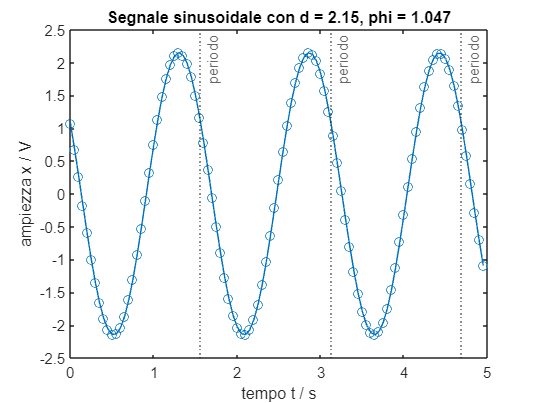

% Calcolare i valori di un segnale sinusoidale campionato, e tracciarne il grafico

% Domande
% Ts = periodo di campionamento
% n = vettore colonna, indice dei campioni da 0 a N-1
% t = vettore colonna, indice degli istanti di campionamento
% Tx = periodo del segnale
% fx = frequenza del segnale
% wx = frequenza angolare del segnale
% x = segnale campionato
% Tracciare un grafico come in figura

% Codice iniziale
clear
N = 100

N = 100

Td = 5

Td = 5

Np = 3.2

Np = 3.2000

d = 2.15

d = 2.1500

phi = pi/3

phi = 1.0472

### Soluzione

Ts = Td/N

Ts = 0.0500

n = [0:N-1]'

n =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


t = n*Ts

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


Tx = Td/Np

Tx = 1.5625

fx = 1/Tx

fx = 0.6400

wx = 2*pi*fx

wx = 4.0212

x = d*cos(wx*t+phi)

x =     1.0750
    0.6815
    0.2605
   -0.1709
   -0.5955
   -0.9961
   -1.3565
   -1.6623
   -1.9011
   -2.0634


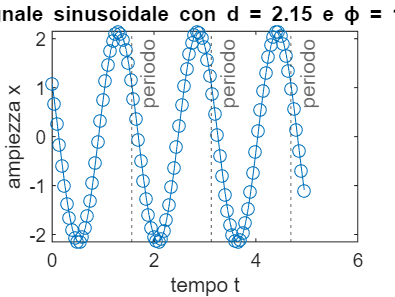

plot(t,x,"-o")
xlabel("tempo t")
ylabel("ampiezza x")
title(sprintf("segnale sinusoidale con d = %.2f e \\phi = %.3f",d,phi))
xline((1:floor(Np))*Tx,":","periodo")

## Grafico di un segnale periodico con ascissa gli indici dei campioni

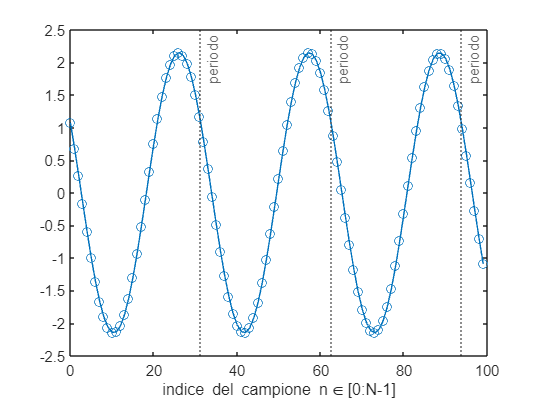

% Dati
% Quelli del quesito precedente

% Domande
% Tracciare un grafico come in figura

### Soluzione

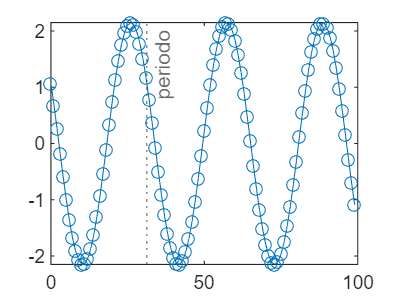

plot(n,x,"-o")
xline(Tx/Ts,":","periodo")

## Grafico di un segnale periodico con ascissa il numero progressivo di periodi

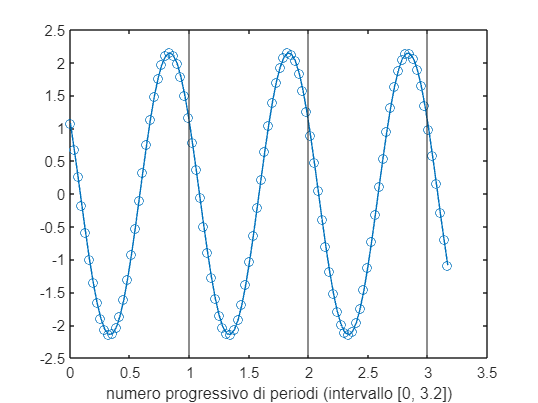

% Dati
% Quelli del quesito precedente

% Domande
% fs = frequenza di campionamento
% fx = frequenza del segnale (già calcolata prima)
% Fx = frequenza digitale (o frequenza normalizzata) del segnale
% Tracciare un grafico come quello in figura

% Nota: Il valore di frequenza digitale del segnale è quello della sua frequenza, 
% se il periodo di campionamento fosse uguale a 1. 
% La frequenza fx si misura in hertz = periodi / secondo
% La frequenza Fx si misura in periodi / campione (è adimensionale)

### Soluzione

fs = 1/Ts

fs = 20

fx

fx = 0.6400

Fx = fx/fs %per definizione

Fx = 0.0320

Fx = Np/N %formula alternativa

Fx = 0.0320

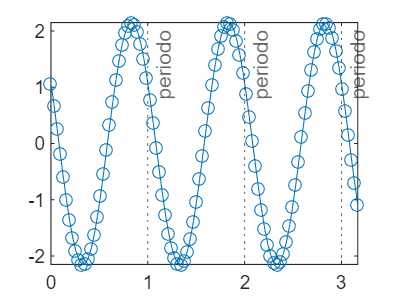

plot(n*Fx,x,"-o")
xline((1:floor(Np)),":","periodo")

## Ricerca di massimo e minimo di un segnale campionato

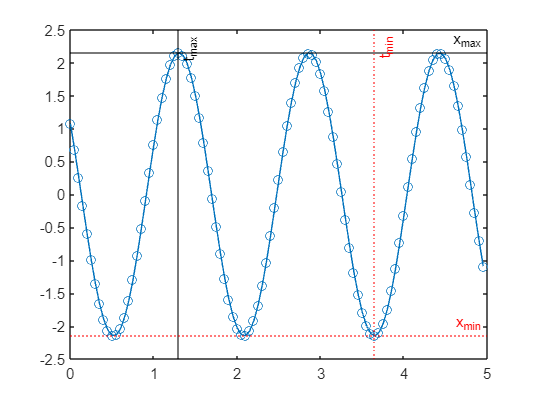

% Dati
% t = istanti di campionamento
% x = segnale campionato

% Domande
% xmax = valore massimo di x
% tmax = istante in cui x = xmax
% xmin = valore minimo di x
% tmin = istante in cui x = xmin
% xpp = valore picco-picco del segnale campionato
% Tracciare un grafico come quello in figura

% Codice iniziale
clearvars -except t x Tx % Tx non ci serve ora
who

### Soluzione

## Ricerca del campione col valore più vicino a una costante assegnata

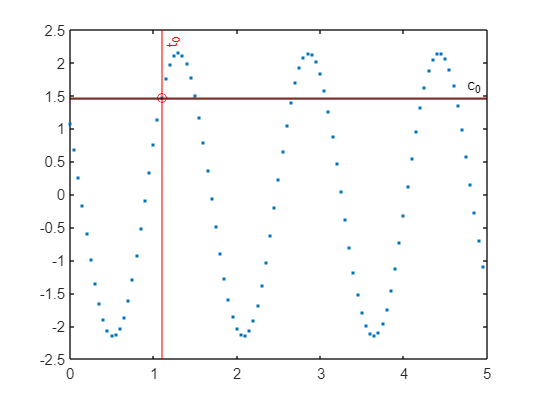

% Dati
% t = istanti di campionamento
% x = segnale campionato
% c0 = costante assegnata

% Domande
% x0 = campione col valore più vicino a c0
% t0 = istante del campione
% Tracciare un grafico come quello in figura.

% Nota
% Nel grafico:
% la linea orizzontale rossa corrisponde a x0
% la linea orizzontale nera corrisponde a c0

% Codice iniziale
c0 = 1.45

### Soluzione

## Ricerca dei primi 3 massimi di un segnale campionato

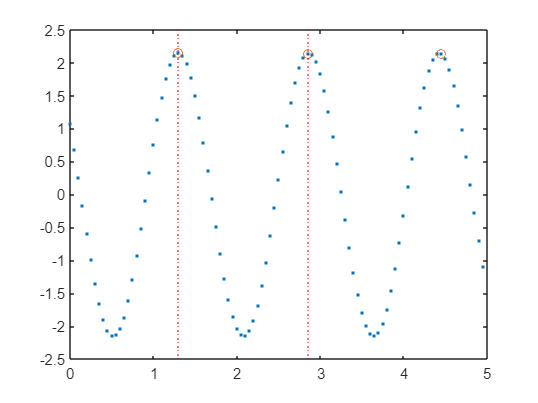

% Dati
% Quelli del quesito precedente
Nmax = 3 % numero di massimi

% Domande
% xmax = vettore dei primi tre massimi dal più grande al più piccolo
% tmax = vettore degli istanti di tempo dei primi tre massimi
% t12 = vettore dei primi due elementi del vettore tmax
% Tx_hat = stima del periodo del segnale in base a t12
% Tracciare un grafico simile a quello in figura

% Nota
% Scrivere il codice iniziando utilizzando la variabile Nmax

### Soluzione

## Calcoli su un gradino esponenziale: tempi di assestamento

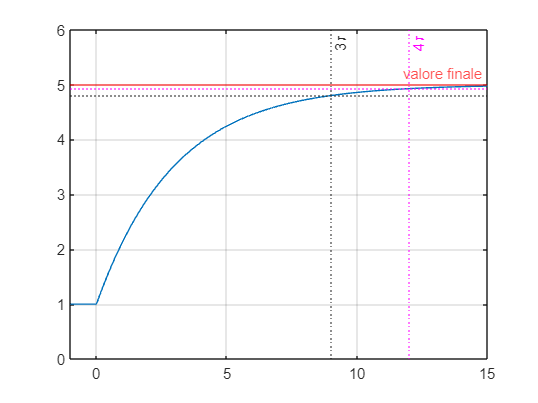

% Questo quesito ha lo scopo di illustrare calcoli utilizzando una funzione
% (nell'esempio, una "funzione anonima"). La funzione è un segnale a
% "gradino esponenziale".

% Dati
% tau = costante di tempo del gradino
% Vbase = valore di tensione iniziale del gradino
% Vpp = valore picco-picco del gradino

% Domande
% f = @(t) funzione "gradino esponenziale" con parametri Vbase, Vpp, tau
% t = vettore colonna di istanti di tempo equispaziati in [-1,15], con Ts = 0.1
% v = vettore colonna dei valori di tensione in t
% Vtop = valore finale del gradino
% e3 = errore se si approssima Vtop con il gradino dopo 3 costanti di tempo
% er3_pc = e3 come percentuale di Vpp
% e4 = errore se si approssima Vtop con il gradino dopo 4 costanti di tempo
% er4_pc = e4 come percentuale di Vpp
% Tracciare anche un grafico come in figura

% Codice iniziale
clear
tau = 3
Vbase = 1
Vpp = 4

### Soluzione

## Calcoli su un gradino esponenziale: tempo di salita

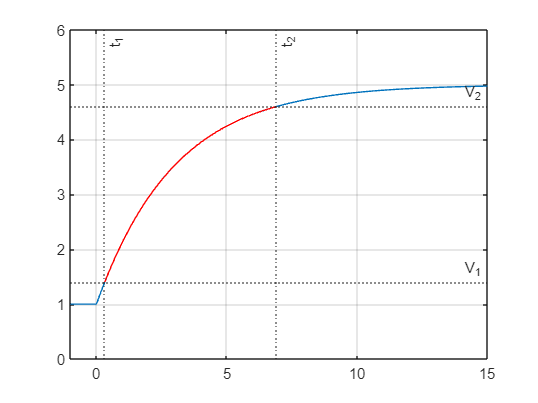

% Dati
% Quelli del quesito precedente

% Domande
% t1 = istante a cui il gradino è salito del 10% di Vpp
% t2 = istante a cui il gradino è salito del 90% di Vpp
% tr = tempo di salita
% Tracciare anche un grafico come quello in figura

### Soluzione